# Control design using state feedback

In this exercise we will design a controller for controlling the speed of a DC motor. 

## Physcial setup

- A common actuator in control systems is the DC motor. It directly provides rotary motion and, coupled with wheels or drums and cables, can provide translational motion.

- The electric equivalent circuit of the armature and the free-body diagram of the rotor are shown in the following figure.

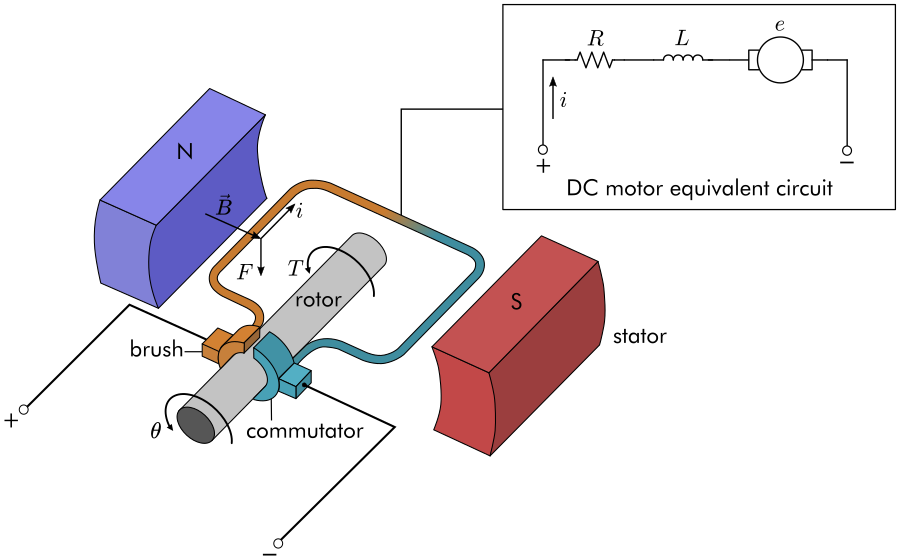

## System equations

- We can derive the following governing equations based on Newton's 2nd law and Kirchhoff's voltage law.


$$iR + L \frac{di}{dt} + k_e \dot{\theta} = v$$


 
$$J \ddot{\theta} + b \dot{\theta}  = k_m i$$
      

We will assume $K = k_e = k_m$

## State space model

- The armature voltage is treated as the input and the rotational speed is chosen as the output

- The state-space representation is therefore:

State vector: $\mathbf{x} = \left[ \begin{array}{c} 
\dot{\theta} \\
i

\end{array} \right]$


$$\dot{\mathbf{x}}  = \left[ \begin{array}{c} 
\ddot{\theta} \\
\dot{i}
\end{array} \right]   =  \left[ \begin{array}{cc}
-\frac{b}{J} &  \frac{K}{J} \\
-\frac{K}{L} & -\frac{R}{L} 
\end{array} \right] \left[ \begin{array}{c} 
\dot{\theta} \\
i
\end{array} \right]

  +  \left[ \begin{array}{c} 
0 \\
\frac{1}{L}  
\end{array} \right] v$$



$$y = \left[ \begin{array}{cc} 1 & 0 \end{array} \right] 
\left[ \begin{array}{c} 
\dot{\theta} \\ 
i
\end{array} \right]$$


## System analysis

J = 0.01; %kg.m^2
b = 0.1; %N.m.s 
K = 0.01; %V/rad/s
R = 1; %Ohm
L = 0.5; %H


%setting up the state space model 
A = [-b/J, K/J; -K/L -R/L]; 
B = [0; 1/L]; 
C = [1 0];
D = 0; 
dcMotorSS = ss(A,B,C,D); 


%Inspect characteristics of step response. 
linearSystemAnalyzer(dcMotorSS)

## Design requirements

First consider that our uncompensated motor rotates at 0.1 rad/sec in steady state for an input voltage of 1 Volt. 

- Settling time less than 2 seconds 

- Overshoot less than 5% (excess speed over reference can damage the motor) 

- Steady-state error less than 1% (because we want to maintain a constant speed) 